# Chemical Reaction - Three Chemical Species

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1 

Solve the system of ODEs, implemented in the local function `reactionODE`.

tRange = [0 3];
Y0 = [100;0;0];
[tSol,YSol] = ode45(@reactionODE,tRange,Y0);

Do not edit. This code plots the solution.

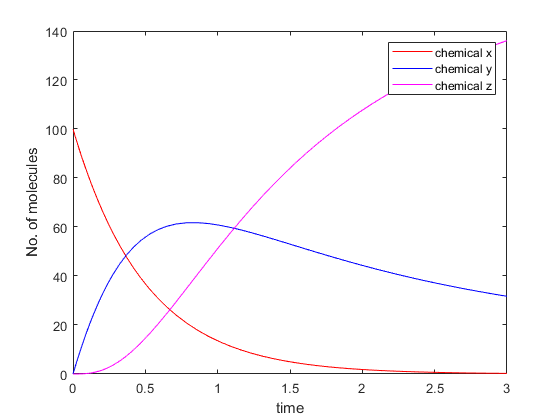

plot(tSol,YSol(:,1),'r')
hold on
plot(tSol,YSol(:,2),'b')
plot(tSol,YSol(:,3),'m')
hold off

% Annotate plot
legend('chemical x','chemical y','chemical z')
xlabel('time')
ylabel('No. of molecules')

## Further Practice

找到y化學物質的最大量時間

y = YSol(:,2);
[ymax,imax] = max(y)

ymax = 61.7609

imax = 51

tmax = tSol(imax)

tmax = 0.8620

**ODE function**

Do not edit. This code defines the ODE function for the system of ODEs

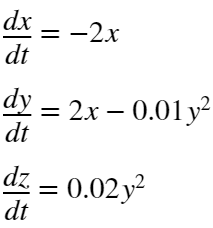

function dYdt = reactionODE(t,Y)
    x = Y(1); % chemical x
    y = Y(2); % chemical y
    z = Y(3); % chemical z
    dxdt = -2*x;
    dydt = 2*x - 0.01*y^2;
    dzdt = 0.02*y^2;
    dYdt = [dxdt;dydt;dzdt];
end
